t = 9;
M = 10;
variance = 0.02;
samples = 1000;
E_oil = 3;
E_air = 1;
frequency = [4 12];
ks = 0;
tmin = 0;
tmax = 10;
thickness_step = 1;
temp = 20;
salinity = 35;
theta = 0;


Scatter plot demo

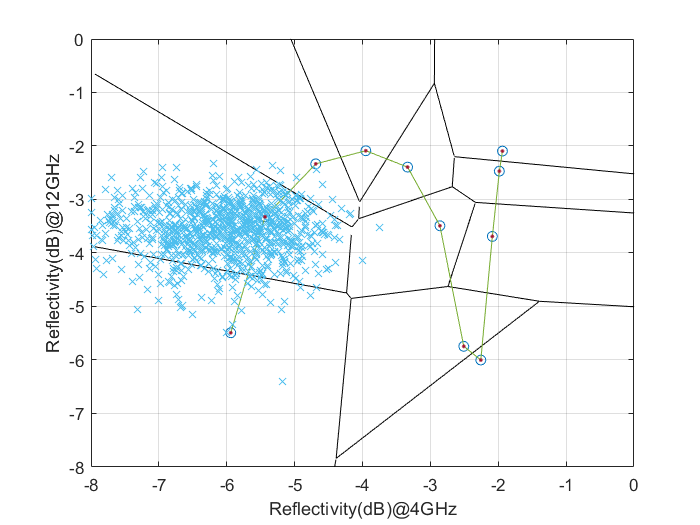

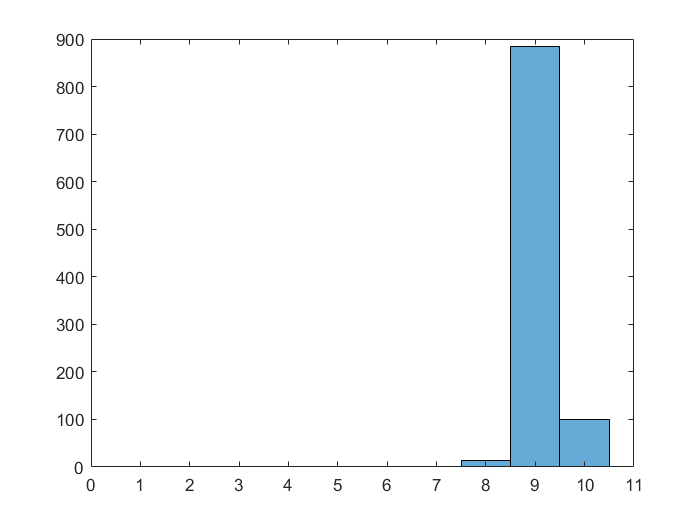



[Estimated_thickness, MaximumError, probability_of_error] = scatterplot(M, frequency, ks, t, variance, samples, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);

Estimate_Thickness demo



thickness = tmin:thickness_step:tmax;
measured_reflectivities = double.empty;

random_thicknesses = (tmax-tmin).*rand(10, 1) + tmin

random_thicknesses =     8.8988
    2.1126
    9.5927
    7.0849
    1.9562
    2.7677
    6.5319
    6.7819
    1.7397
    2.4246



%generate reflectivity values
for i =1:1:length(frequency)
    measured_reflectivities(:, :, i) = reflectivity(frequency(i), random_thicknesses, ks, E_oil, E_air, temp, salinity, theta);
end

Estimated_thicknesses = Estimate_Thickness(measured_reflectivities, M, frequency, ks,  variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax)

Estimated_thicknesses =      9
     2
    10
     7
     2
     2
     7
     6
     2
     4
